#  Satelite Angle Orientation Control with Fuzzy PI Controller

## Linear PI Controller

We are given with a closed loop system (Fig. 1), which controls the satelite's orientation angle $y$ through the controller

$G_{c\;} \left(s\right)=K_p \frac{\left(s+c\right)}{s}$, where $c=\frac{K_I }{K_p }$: 

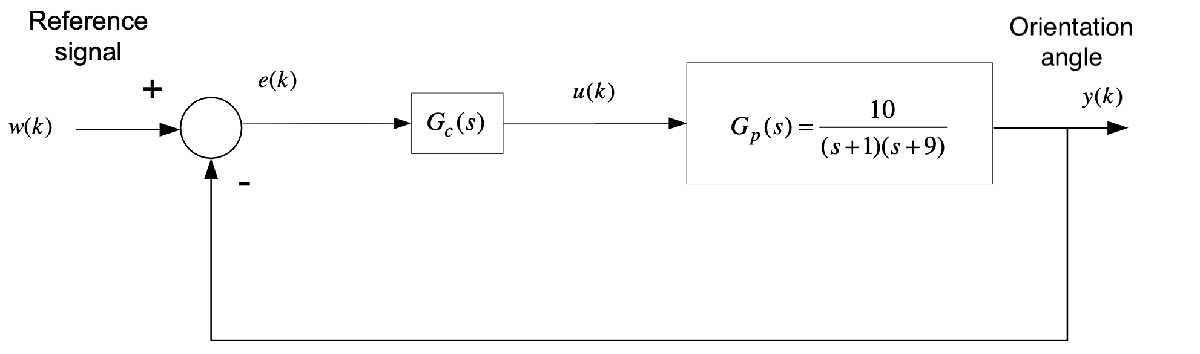

Fig. 1 Linear Closed Loop

After implementing that in MATLAB code, we must tune its parameters according to certain requirements. Specifically, we have to achieve: 

- overshoot < 10% 

- rise time < 1.2 seconds

clc; clearvars; close all;
addpath("lib")
addpath("sim")
% Define the system
SystemPoles = [-1, -9];
SystemGain = 10;
Gp = zpk([], SystemPoles, SystemGain); % Plant system

% Initial PI controller setup (not optimal)
ControllerZero = -1.3;
ControllerPole = 0;
ControllerGain = 1;
Gc = zpk(ControllerZero, ControllerPole, ControllerGain);

% Use the toolbox to tune the controller

% controlSystemDesigner(Gp, Gc); % Uncomment for tuning

We utilize Control System Designer to tune parameters to: 

 
$$K_p =1\ldotp 378,{\;K}_I =1\ldotp 9035,\;c=1\ldotp 38$$


and select the following settings:

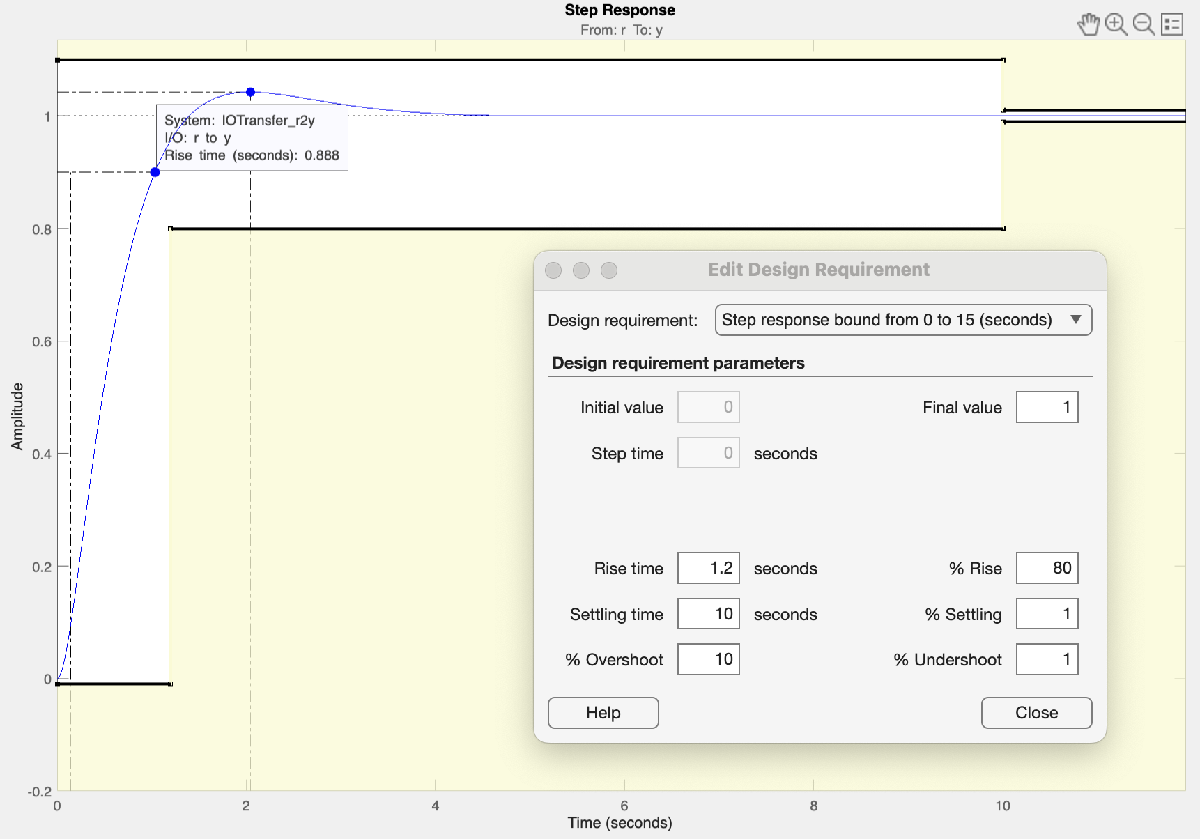

Fig. 2 Step Response and Settings

% After saving the session so I don't have to tune it everytime:
% load("FinalControlSystemSession.mat");

TunedSession = load("FinalControlSystemSession.mat");
ControllerData = TunedSession.ControlSystemDesignerSession.DesignerData.Designs.Data;
Gc = ControllerData.C % Extract the tuned PI Controller

Gc =
 
  1.378 (s+1.381)
  ---------------
         s
 
Name: C
Continuous-time zero/pole/gain model.
Model Properties


% Construct the closed loop system
sys_open_loop = Gp * Gc;
sys_closed_loop = feedback(sys_open_loop, 1, -1)

sys_closed_loop =
 
          13.78 (s+1.381)
  --------------------------------
  (s+7.205) (s^2 + 2.795s + 2.642)
 
Continuous-time zero/pole/gain model.
Model Properties


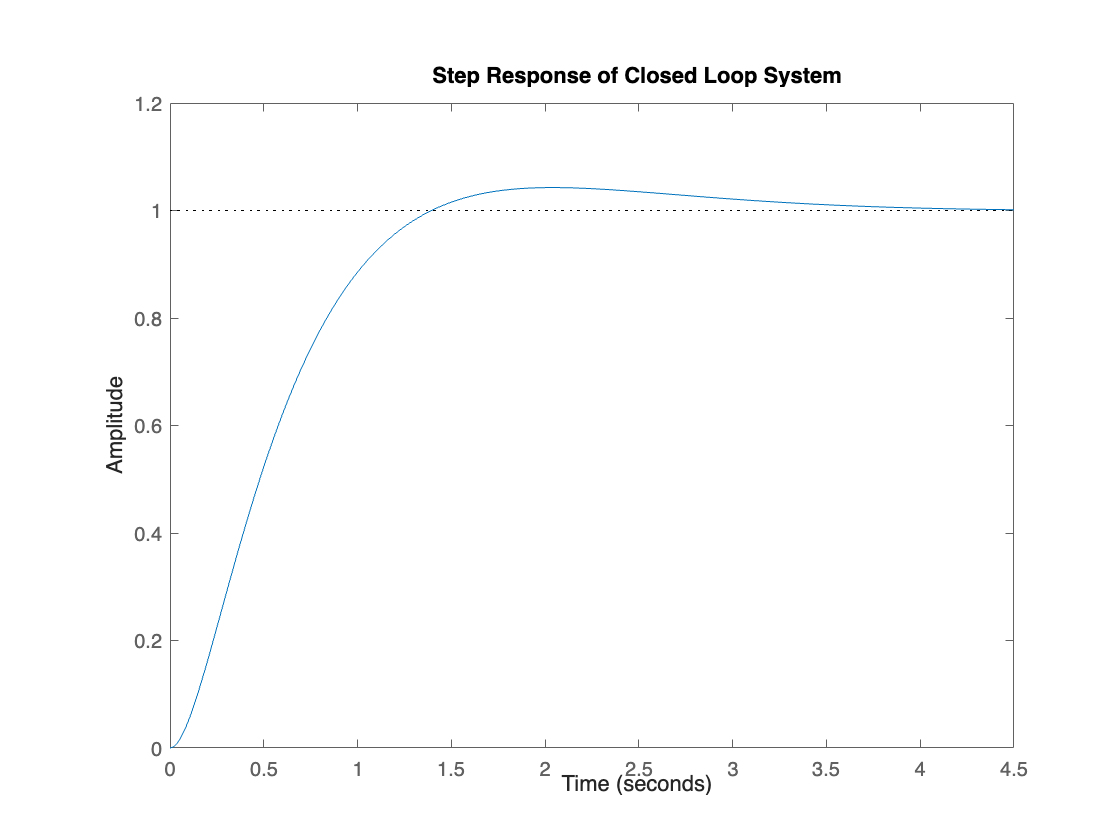

% Plot the step response of the closed-loop system
figure;
step(sys_closed_loop);
title('Step Response of Closed Loop System');

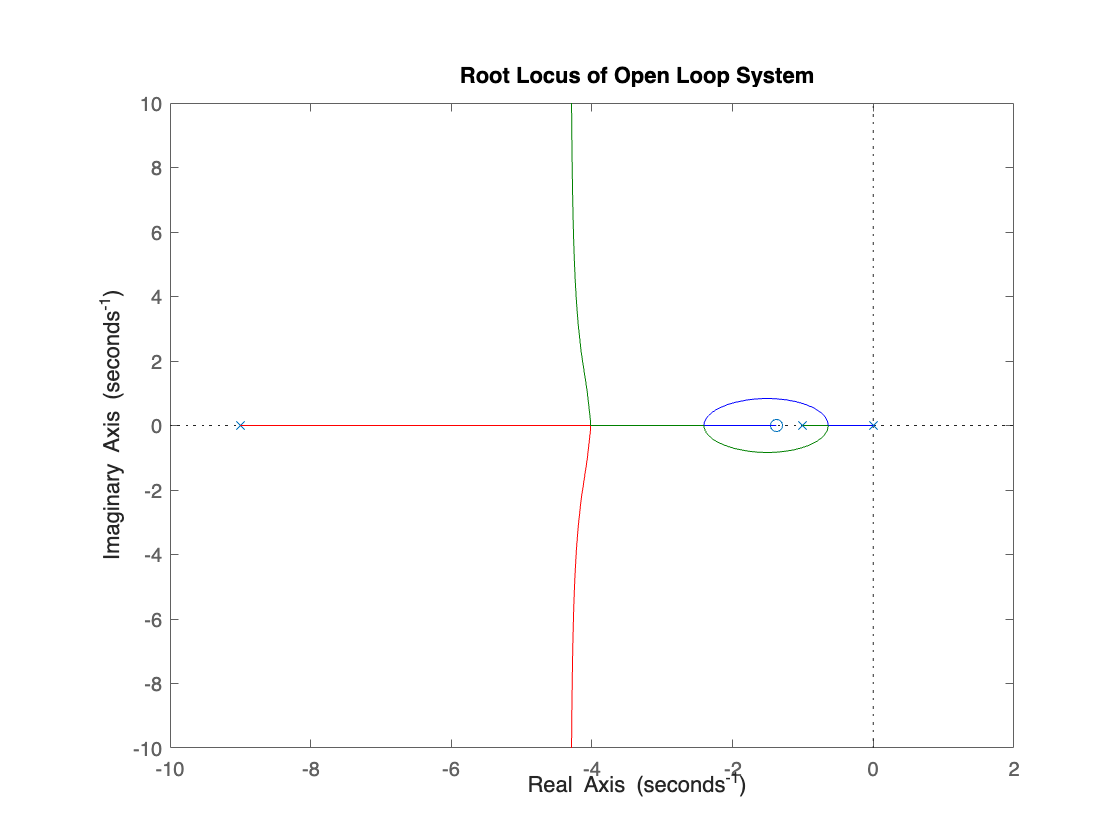

% Plot the root locus of the open-loop system
figure;
rlocus(sys_open_loop);
title('Root Locus of Open Loop System');

% Compute the proportional and integral gains based on the closed-loop system
ProportionalGainFactor = 10;
ProportionalGain = sys_closed_loop.K / ProportionalGainFactor;
IntegralGain = -sys_closed_loop.Z{1,1} * ProportionalGain;

% Obtain step response data
[y, t] = step(sys_closed_loop);

% Calculate step response information
info = stepinfo(y, t)

info = struct with fields:
         RiseTime: 0.8915
    TransientTime: 2.9755
     SettlingTime: 2.9755
      SettlingMin: 0.9055
      SettlingMax: 1.0427
        Overshoot: 4.0763
       Undershoot: 0
             Peak: 1.0427
         PeakTime: 2.0453


## Fuzzy PI Controller

Now, we create a PI Fuzzy Logic Controller. We consider as inputs the tracking error $e$ and its time derivative $\dot{e}$, while the output is the derivative of the control singal $\dot{u}$. 

The membership function for the inputs and output is defined by the following figure:

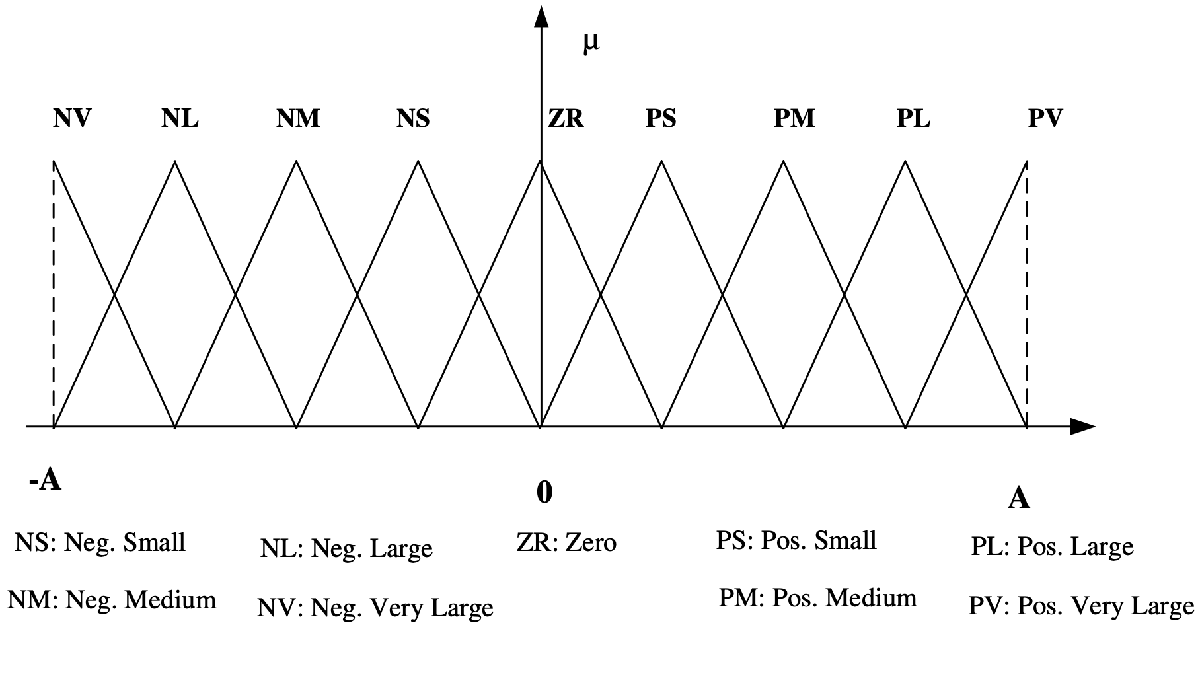

Fig.3 Verbal Variable Values

Firstly, we create the rulebase.m according to the instructions. The rules of the controller are defined from the following table (Fig. 4), which shows the outputs for all the combinations of inputs:

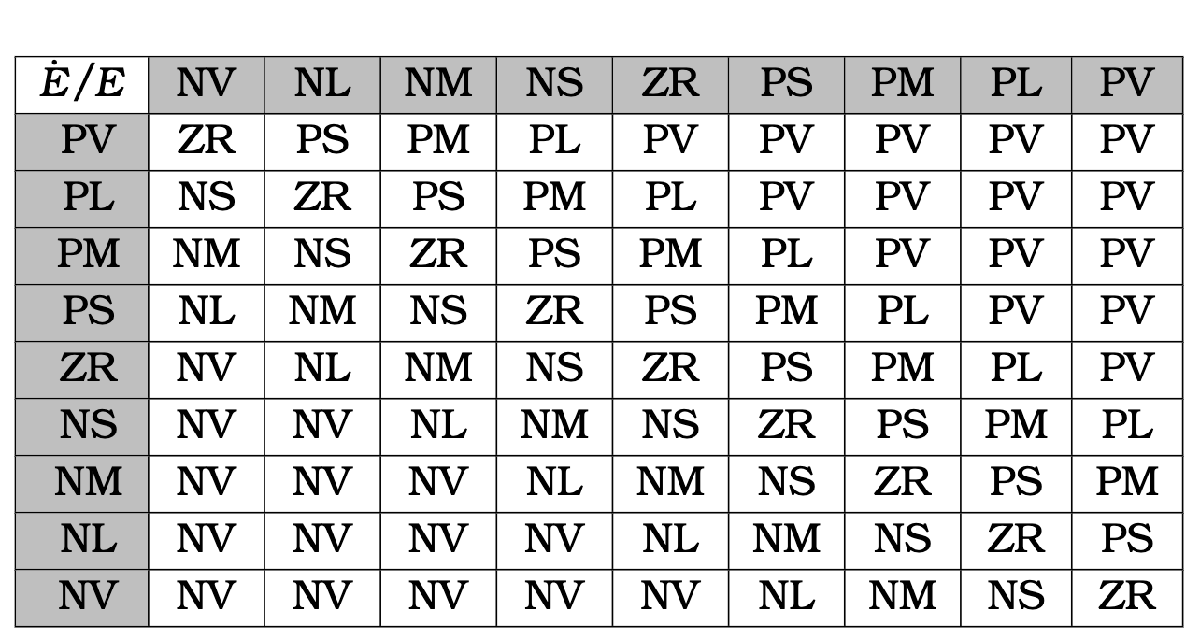

Fig. 4 Rulebase

Following that, we need to create the controller.

% The fis was created executing fuzzy_rulebase.m
FLC = readfis('FLC')

FLC =   mamfis with properties:

                       Name: "FLC"
                  AndMethod: "min"
                   OrMethod: "max"
          ImplicationMethod: "min"
          AggregationMethod: "max"
      DefuzzificationMethod: "centroid"
    DisableStructuralChecks: 0
                     Inputs: [1×2 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×81 fisrule]

	See 'getTunableSettings' method for parameter optimization.


We create the following initial system on Simulink to compare with Linear PI:

%initial_simFLC % Uncomment to run, it might need manual FLC loading through simulink

We normalize and denormalize the reference and output signals respectively, taking under consideration that they are in $\left\lbrack 0,60\right\rbrack$. Also,we use saturation function to fix the inputs of the FLC between -1 and 1 values.

### Scenario 1

#### a) Controller Design and System Response

Firstly we create and tune the system with the same gain values as the tuned Linear PI controller, namely:  $K_e =1,{\;K}_I =1\ldotp 9035,a=0\ldotp 7239$.

We also created alongside the Linear Controller so as to run the simulation simultaneously for easier comparison (simulation file: *initial_simFLC.slx*)

For those parameters, the fuzzy system compared to the Linear PI, responded as: 

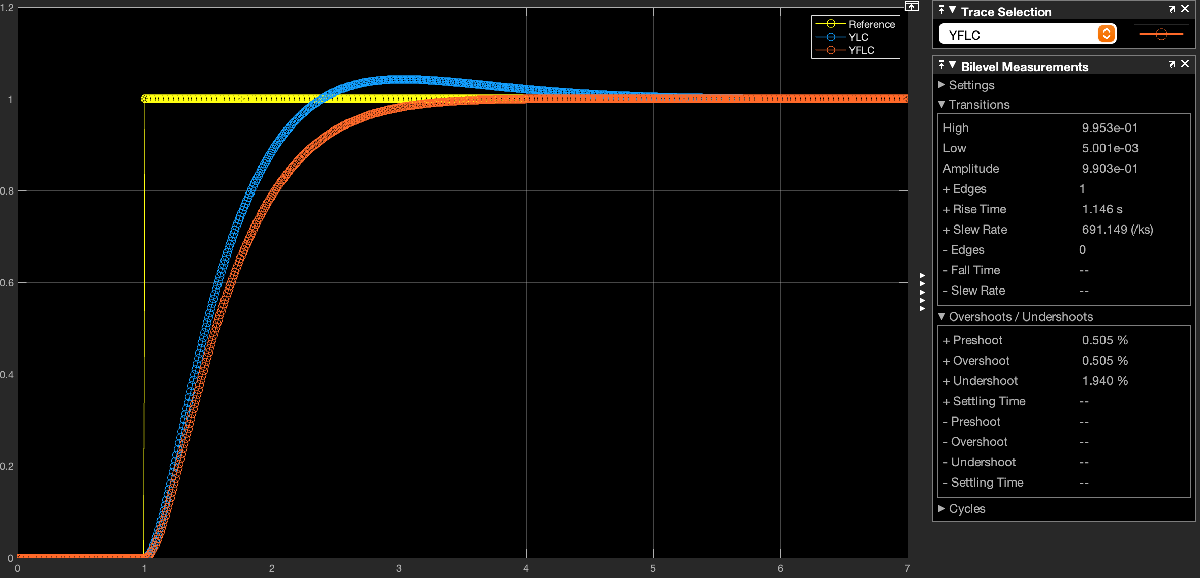

Fig. 5 Linear vs Fuzzy step response

From that we can see that despite having less overshoot (0.505%), it has a more rise time (1.146s), thus not satisfying the criteria of having less overshoot and lower rise time than the Linear PI. So we must continue fine tuning it towards meeting that goal. 

In order to achieve that, we must test the effect of those three parameters on the system so as to formulate a final decision. Below we can see the different responses our fuzzy system has depending on the variables' changes. For that, we used Model Data Editor through simulink direcly.

Below we can view the step response of the fuzzy system, when keeping two out of the three ($K_e ,{\;K}_I ,\;a$) variables the same, whilst testing different values on the other. 

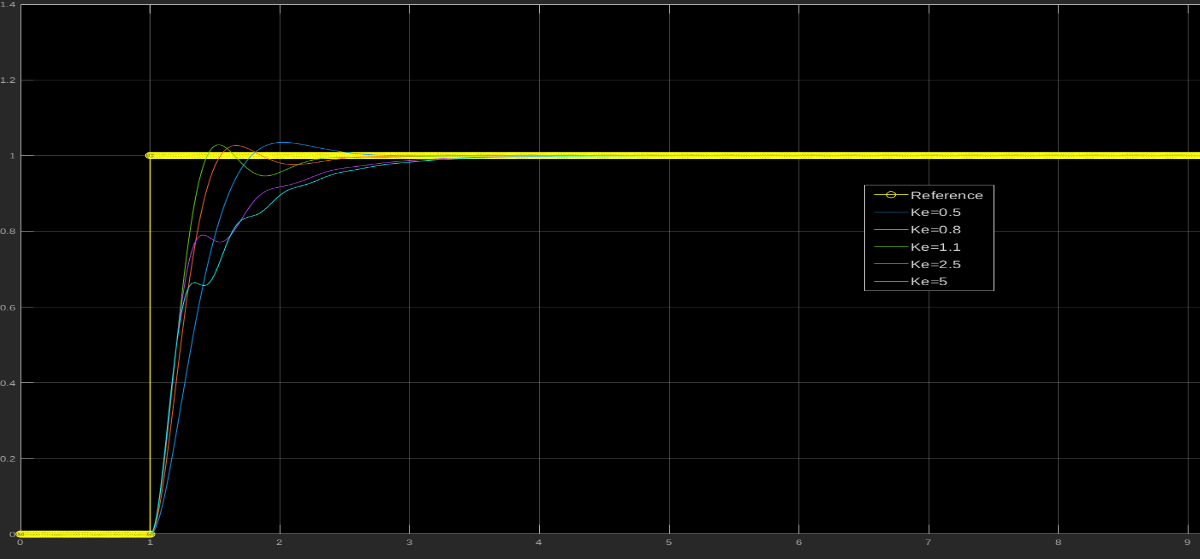

Fig. 6 Effect of $K_e$

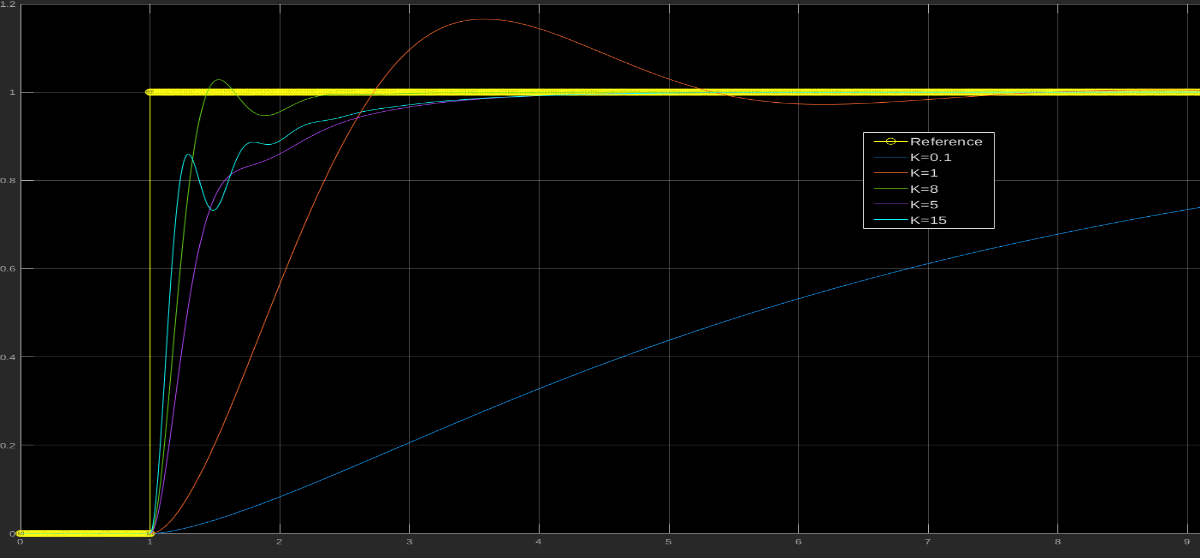

Fig. 7 Effect of $K_1$

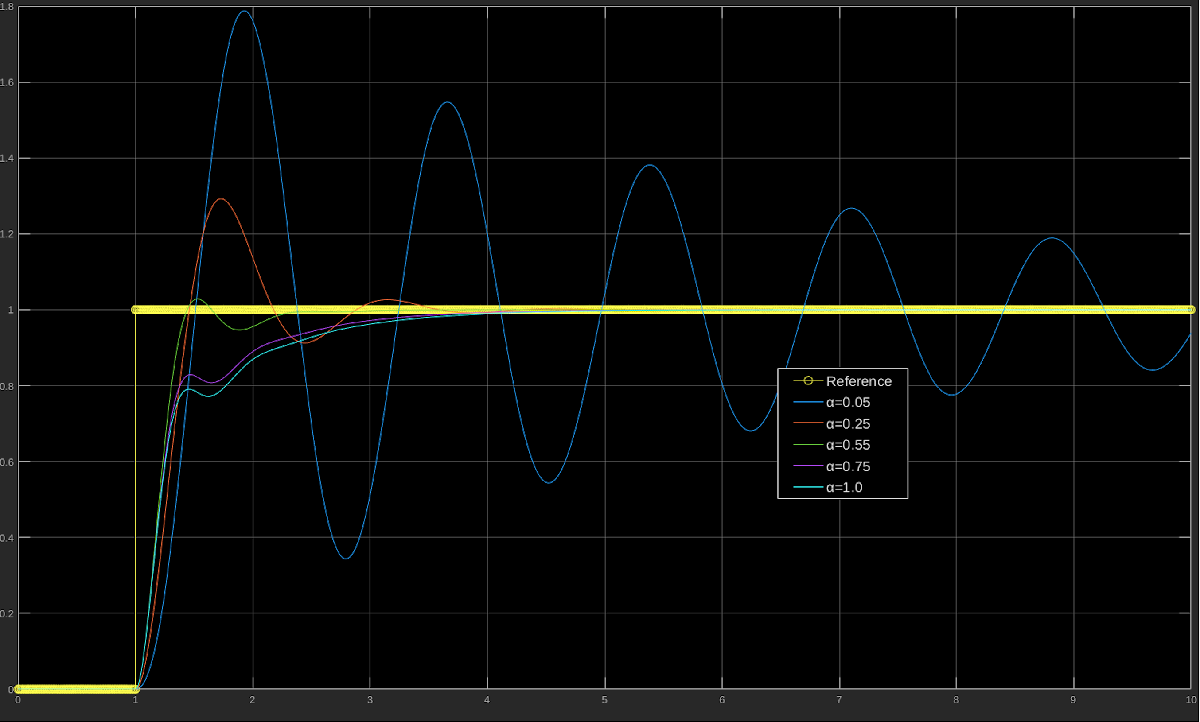

Fig. 8 Effect of $a$

Through theory and testing, we can observe that we need $K_e$ close to 1, also by increasing the${\;K}_I$ gain, we can acheive a faster response with a smaller error, but we may get an unstable system, finally by modifying variable α we can achieve a faster response but we also migh destabilize the system by giving it really low values, which as we can see has the system oscillating.

After the trial and error, and after seeing which values more closely match the step's reposne, we managed to tune the system so as it has a less overshoot than the linear and the goal of 7%, and also with faster rise time, under the given threshold of 0.8s.

The parameters that suit the aforementioned criteria are: $K_e =1\ldotp 1,{\;K}_I =8,a=0\ldotp 55$ and the system can be simulated (tuned), live below.

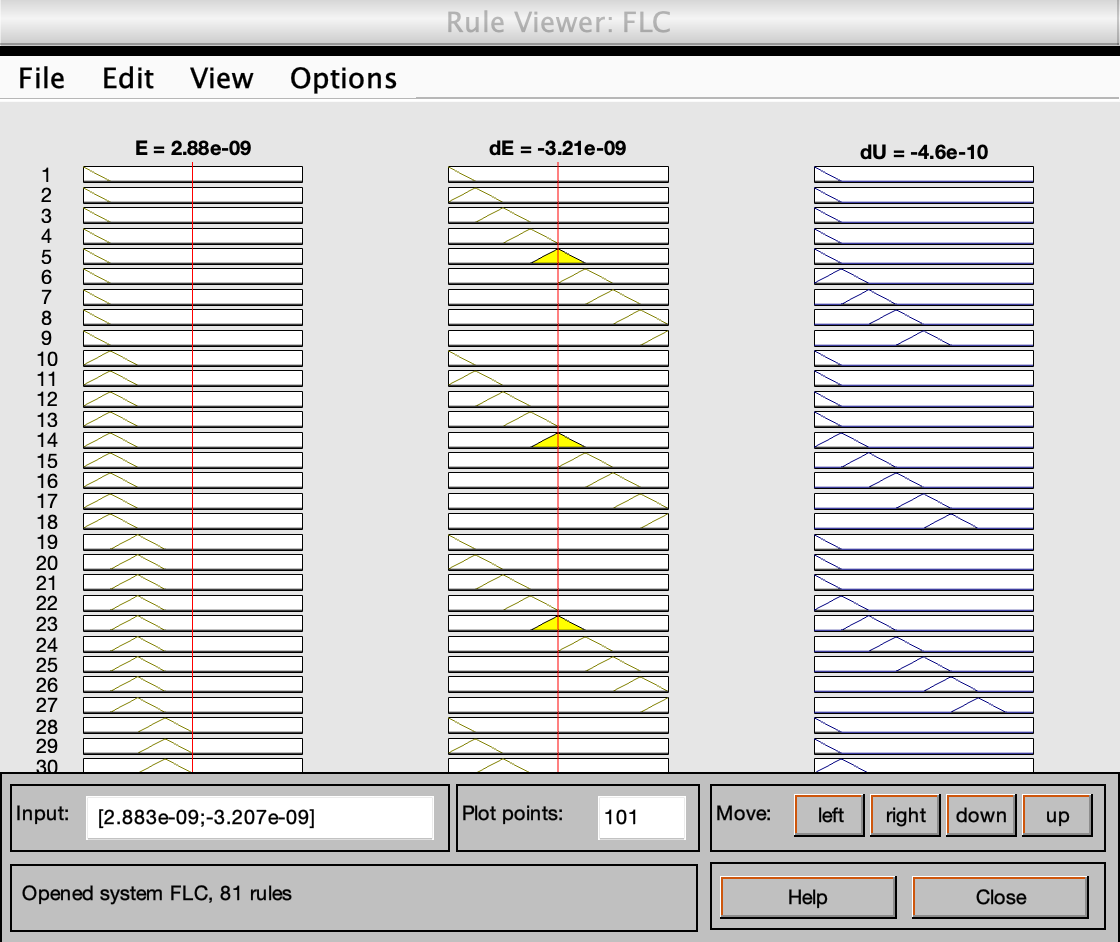

simout =   Simulink.SimulationOutput:

              ScopeData: [1x1 Simulink.SimulationData.Dataset] 
                logsout: [1x1 Simulink.SimulationData.Dataset] 
                   tout: [701x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


simout = sim('simFLC')

We retrieve the data from the simulation, and plot them directly, and so we can see that with these parameters, the fuzzy PI responds better than the Linear PI.

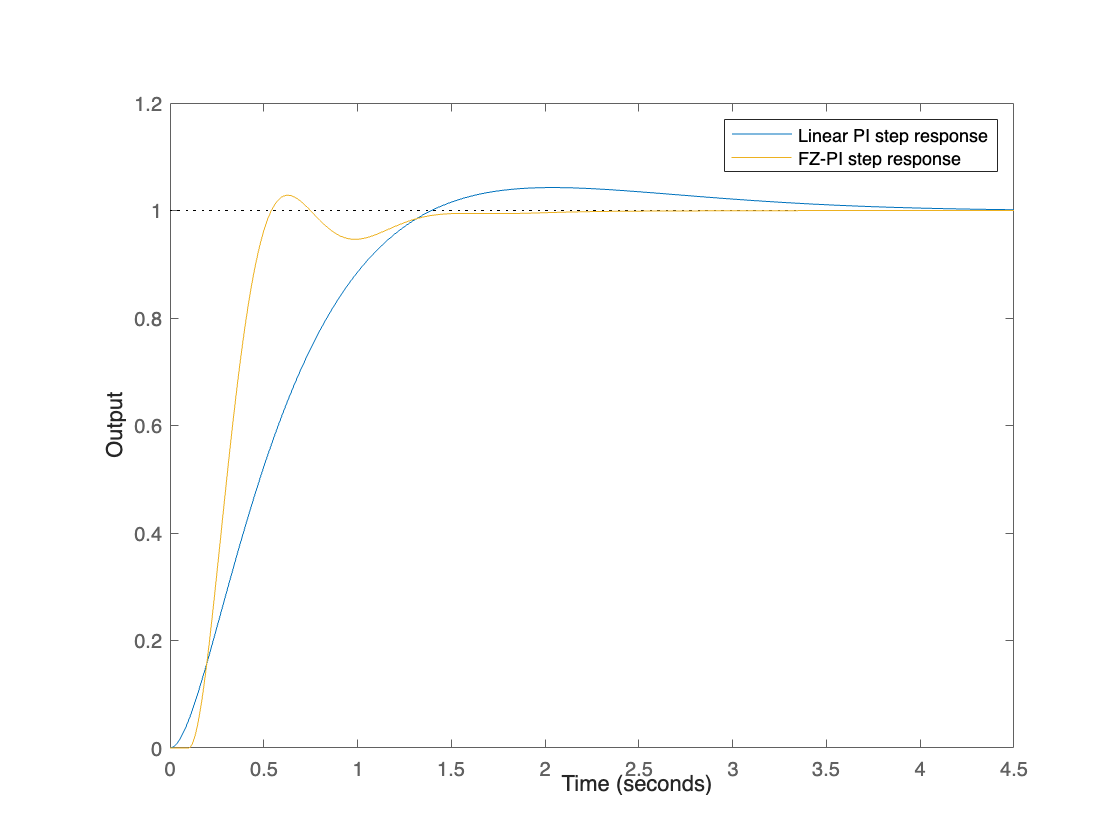

data = simout.logsout;
fzOut = data.get('YFLC');
% scopeSignalData = simout.ScopeData1{1};
% data = scopeSignalData.Values.Data;
% time = scopeSignalData.Values.Time;

figure()
hold on;
step(sys_closed_loop);
plot(simout.tout, simout.logsout.get('YFLC').Values.Data(:,1));
xlabel('Time');
ylabel('Output');
title('');
legend('Linear PI step response', 'FZ-PI step response');
hold off;

We can validate that the Fuzzy PI Controller performs better in terms of overshoot and rise time:

stepinfo(fzOut.Values.Data(:,1), simout.tout)

ans = struct with fields:
         RiseTime: 0.2822
    TransientTime: 1.2709
     SettlingTime: 1.2709
      SettlingMin: 0.9061
      SettlingMax: 1.0284
        Overshoot: 2.8374
       Undershoot: 0
             Peak: 1.0284
         PeakTime: 0.6300


Thus satisfiying the requirements for both overshoot and rise time to be below the linear PI's, and below the given threshold of 7% and 0.8 sec.

#### b) Base Functionality

After implementing the rulebase design, we now test its functionality. We assume the FLC inputs $e=\textrm{PS}$ and $\Delta e=\textrm{PS}$. According to Fig.4, we should expect an output of $\Delta U=\textrm{PM}$.

FLC = readfis('FLC');
% Define the linguistic inputs
linguistic_inputs = [0.25, 0.25];  % PS corresponds to 0.25

% Evaluate the FLC
result = evalfis(FLC, linguistic_inputs);

% Display the result
disp(['The result of dU is: ', num2str(result)]);

The result of dU is: 0.5


Which according to the rulebase, corresponds to "PM". We can verify that below, and also through Fig. 9

disp(['The corresponding linguistic value for E is ', FLC.Inputs(1).MembershipFunctions(6).Name, ' with value ', num2str(FLC.Inputs(1).MembershipFunctions(6).Parameters(2))]);

    "The corresponding linguistic value for E is "    "PS"    " with value "    "0.25"



disp(['The corresponding linguistic value for dE is ', FLC.Inputs(2).MembershipFunctions(6).Name, ' with value ', num2str(FLC.Inputs(2).MembershipFunctions(6).Parameters(2))]);

    "The corresponding linguistic value for dE is "    "PS"    " with value "    "0.25"



disp(['The corresponding linguistic value for dU is ', FLC.Outputs(1).MembershipFunctions(7).Name, ' with value ', FLC.Outputs(1).MembershipFunctions(7).Parameters(2)]);

    "The corresponding linguistic value for dU is "    "PM"    " with value "    "0.5"



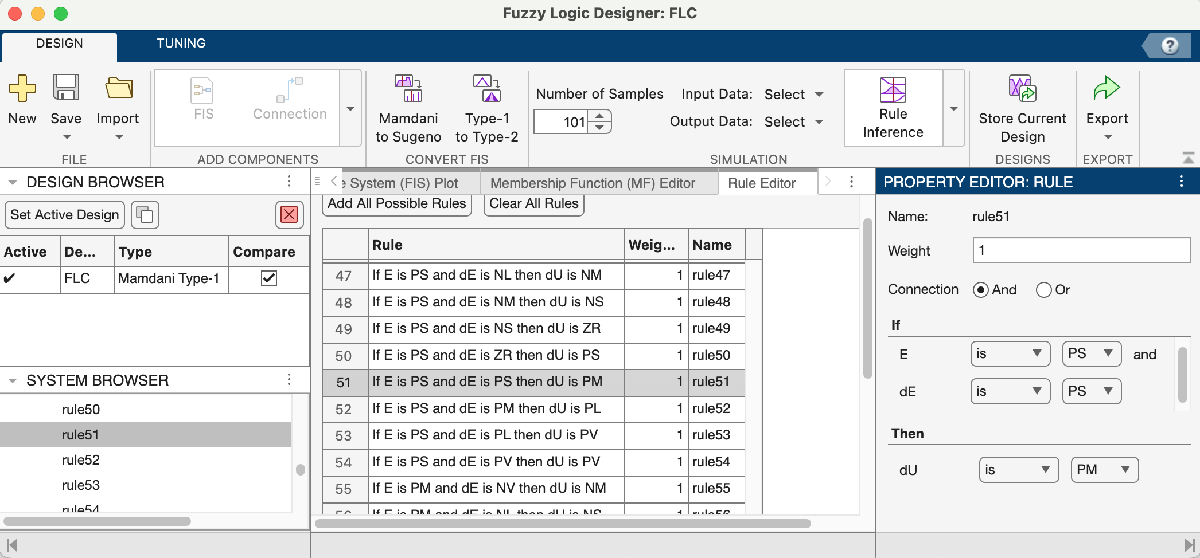

Fig. 9 Fuzzy Logic Designer Toolbox rule 51

#### c) Visualize Fuzzy Controller Output in 3D

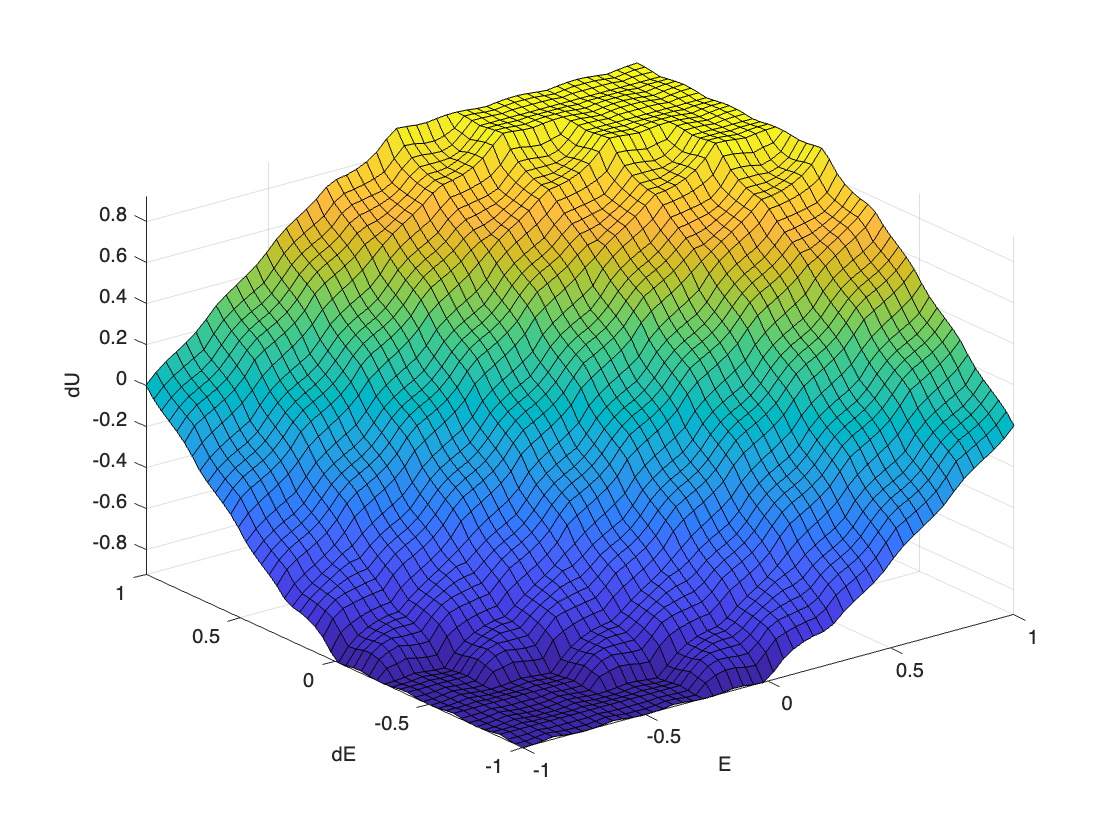

figure()
opt = gensurfOptions('NumGridPoints', 50);
gensurf(FLC, opt)

The fuzzy rulebase defines how the controller responds to different error and rate of change scenarios. It aims to keep the system output close to the reference signal. The controller adjusts its actions based on whether the error is positive or negative and whether the rate of change is increasing or decreasing. In essence, it strives to minimize deviations from the reference signal and maintain system equilibrium.

### Scenario 2

We will now move forward by testing our tuned system in two different reference signals, in order to see its behaviour.

#### a) Double Step Input

First we will test in a double step like reference signal as seen in the Fig. 10 below.

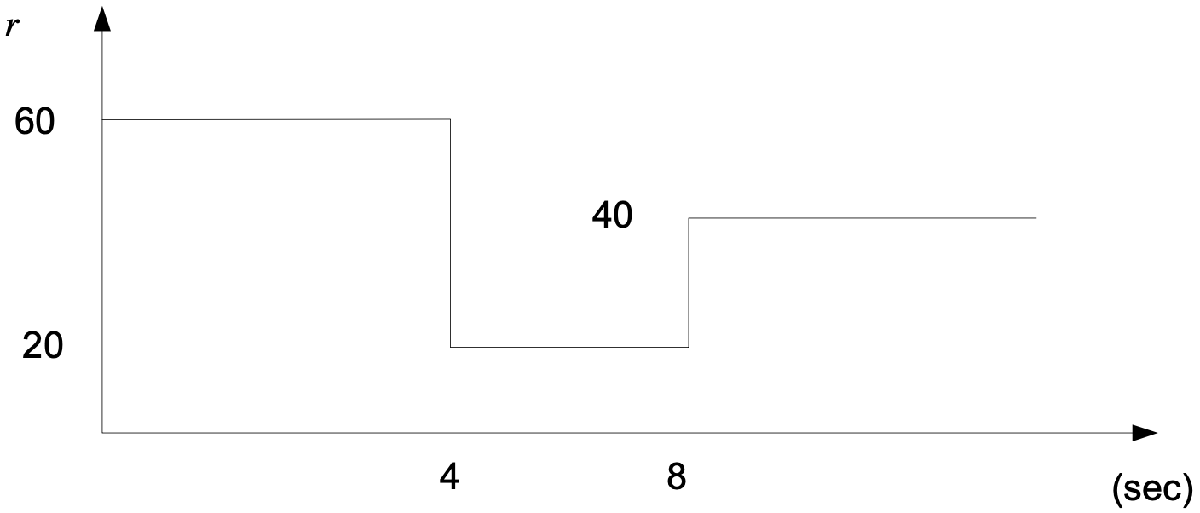

Fig. 10 Double Step Reference Signal

FLC = readfis('FLC')

FLC =   mamfis with properties:

                       Name: "FLC"
                  AndMethod: "min"
                   OrMethod: "max"
          ImplicationMethod: "min"
          AggregationMethod: "max"
      DefuzzificationMethod: "centroid"
    DisableStructuralChecks: 0
                     Inputs: [1×2 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×81 fisrule]

	See 'getTunableSettings' method for parameter optimization.


warning('off', 'all');
step_simout = sim('double_step_simFLC')

step_simout =   Simulink.SimulationOutput:

             ScopeData1: [1x1 Simulink.SimulationData.Dataset] 
                logsout: [1x1 Simulink.SimulationData.Dataset] 
                   tout: [2050x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


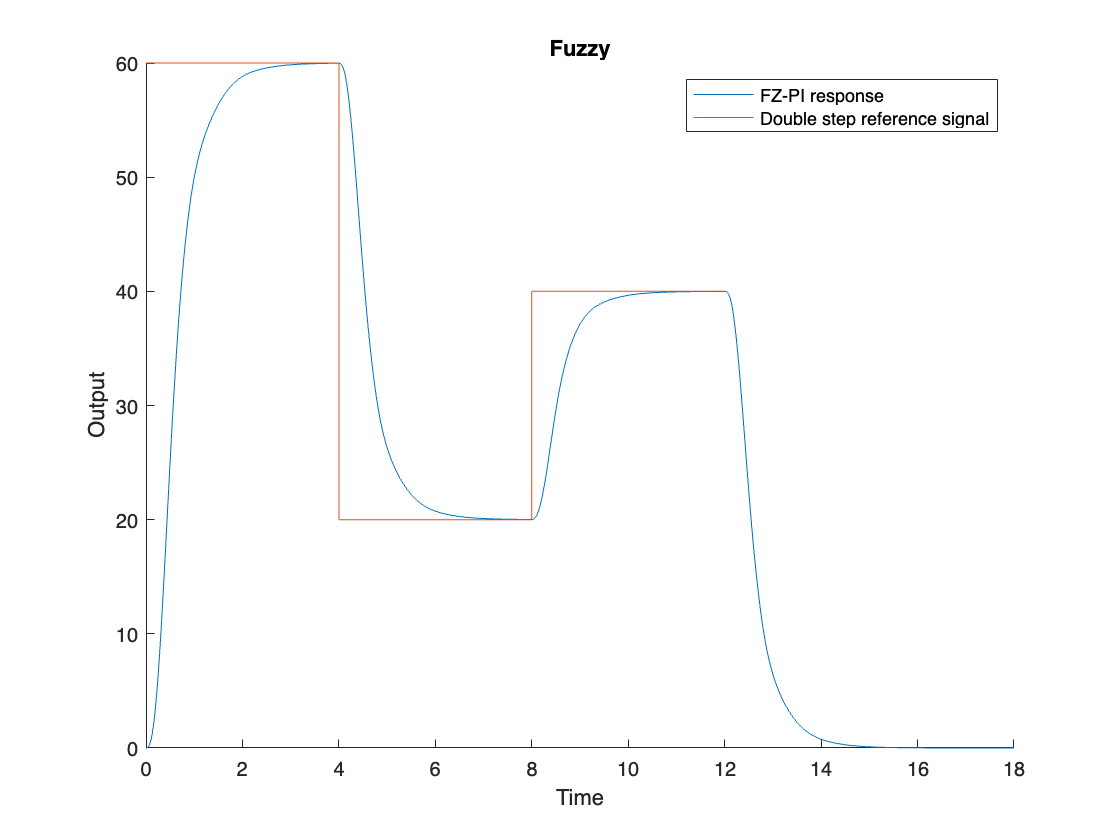

load('SignalScenarios.mat')
ref_dstep_signal = Step.get('Signal 1');
ref_dstep_time = ref_dstep_signal.Time;
ref_dstep_data = ref_dstep_signal.Data;

dstep_data = step_simout.logsout;
fz_2step_signal = dstep_data.get('YFLC');

figure();
hold on;
plot(step_simout.tout, fz_2step_signal.Values.Data(:,1));
plot(ref_dstep_time, ref_dstep_data);
xlabel('Time');
ylabel('Output');
title('Fuzzy');
legend('FZ-PI response', 'Double step reference signal');
hold off;

We can notice that the way we had tuned the system in order to closely follow the step response, does not mean that it can follow any reference signal. Specifically we see that the parameters we chose for the step reference signal previously, has a really slow rise time, and generally response time in the changes by the reference signal. Ofcourse we do not see any (at least significant) overshoot simply because of the low response times.

#### b) Ramp Input

Next we will test our system's ability to follow the following reference signal.

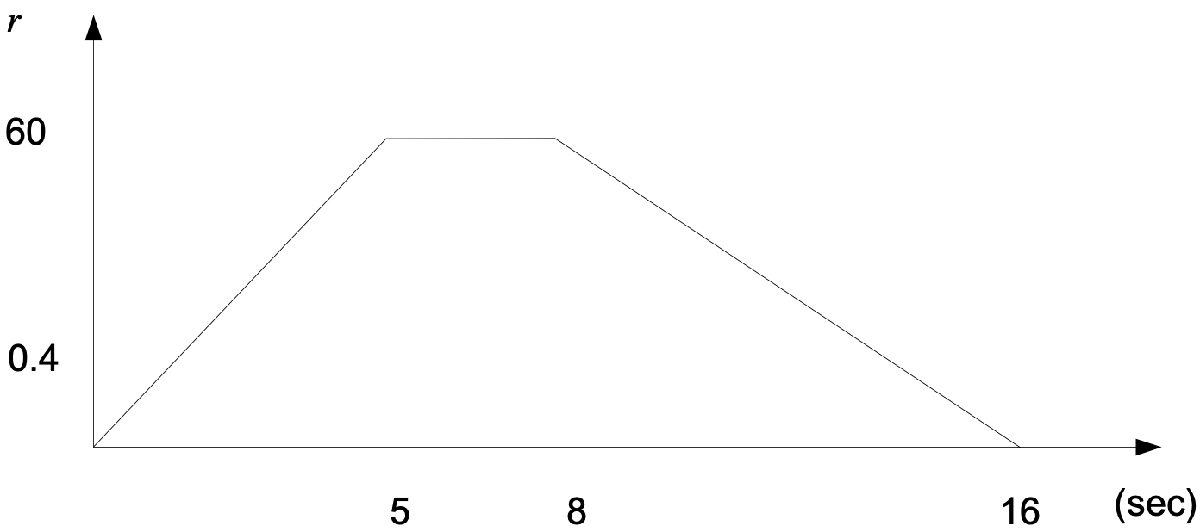

Fig. 11 Ramp Reference Signal

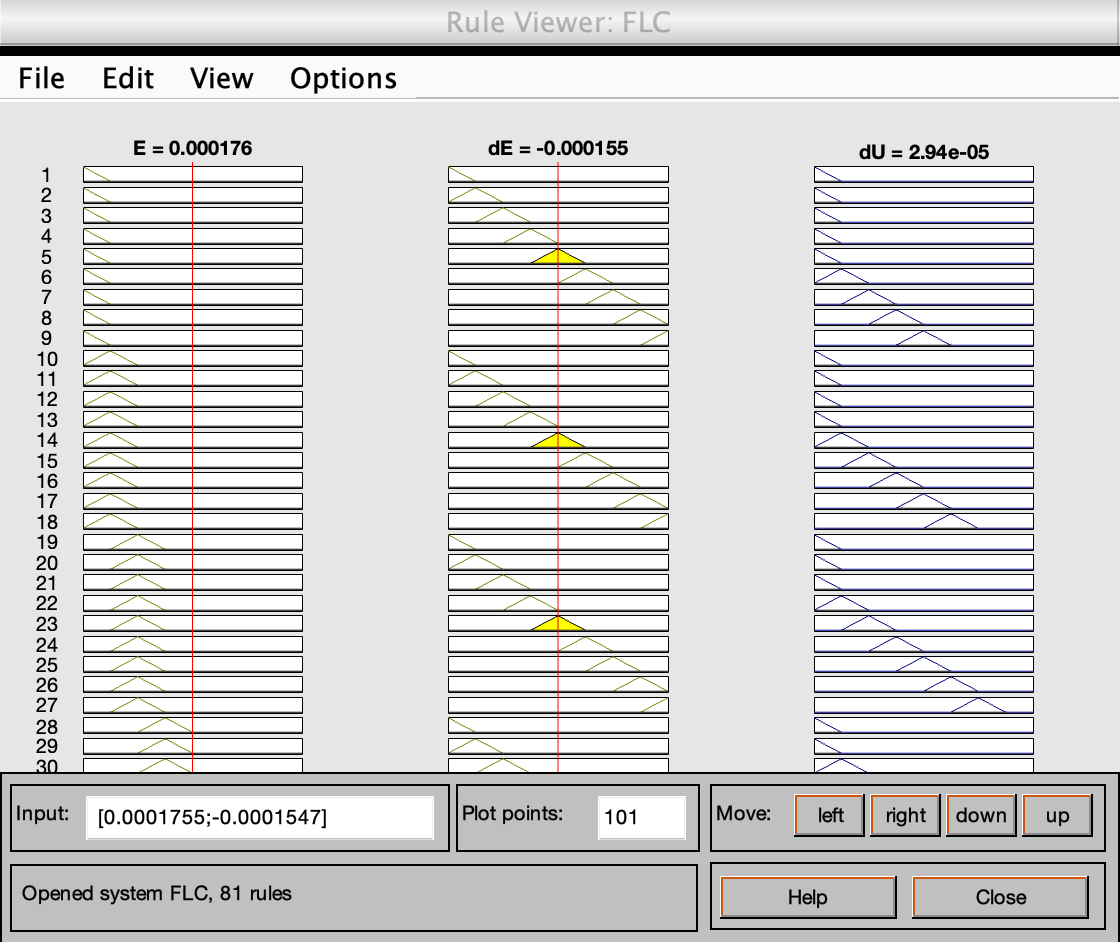

ramp_simout =   Simulink.SimulationOutput:

             ScopeData1: [1x1 Simulink.SimulationData.Dataset] 
                logsout: [1x1 Simulink.SimulationData.Dataset] 
                   tout: [1801x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


warning('off', 'all');
ramp_simout = sim('ramp_simFLC')

Now we test the ability of the controller to track custom inputs signals. The results of the simulations are presented below. The tracking is very accurate, with low overshoots and high rise times. There are some little oscillations too.

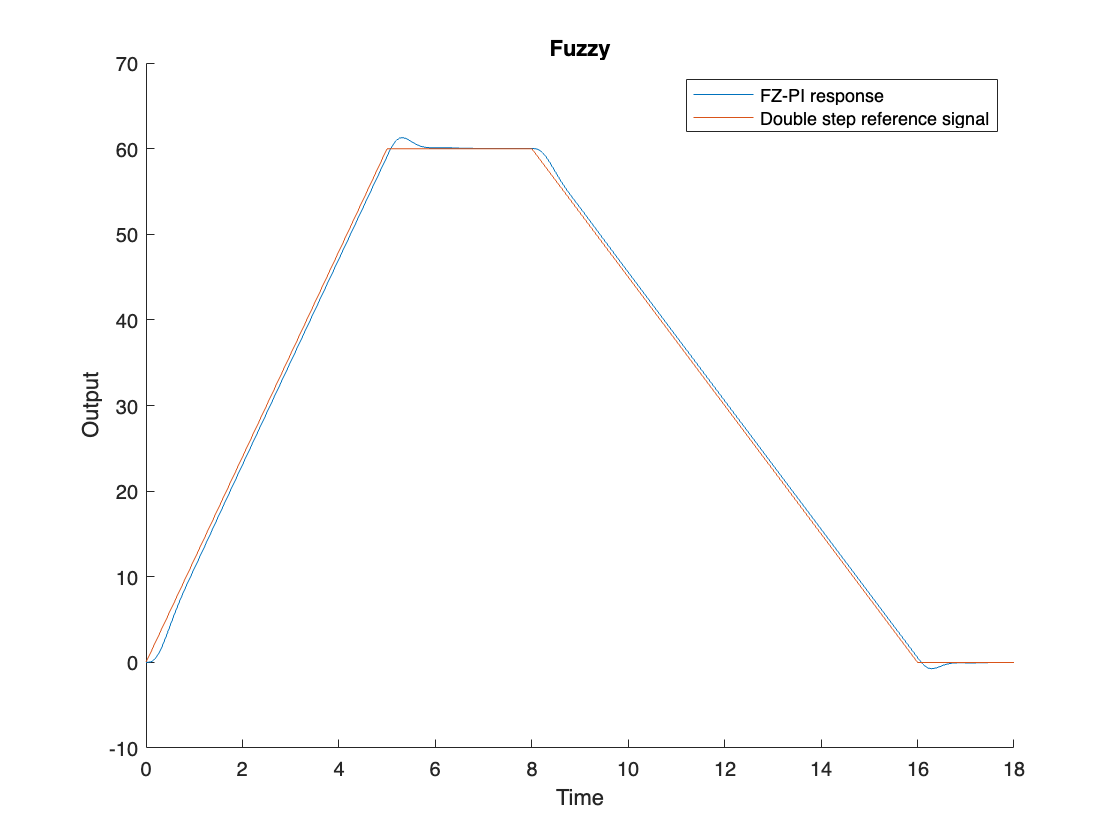

load('SignalScenarios.mat')
ref_ramp_signal = Ramp.get('Signal 1');
ref_ramp_time = ref_ramp_signal.Time;
ref_ramp_data = ref_ramp_signal.Data;

ramp_data = ramp_simout.logsout;
fz_ramp_signal = ramp_data.get('YFLC');

figure();
hold on;
plot(ramp_simout.tout, fz_ramp_signal.Values.Data(:,1));
plot(ref_ramp_time, ref_ramp_data);
xlabel('Time');
ylabel('Output');
title('Fuzzy');
legend('FZ-PI response', 'Double step reference signal');
hold off;

warning('on', 'all');

We can notice here that, surpirisingly, the preivously step-fine-tuned system we implemented, works arguably very good in following the ramp reference system. We can attest that to the 'smoot' transitions between the states, since its not as abrupt as the step function, thus there is no significant problem for our system. So regarding the rise time, we have a system that is behaving very well. With regard to overshoot though, we could say that there exists a significant amount, without it being too much so as to destabilize the system.